% 假设白云石中的初始U（VI）含量为0.1-1 ppm，对应的还原过程中U（IV）/U(IV+VI)比值变化

clear all; clc
data = xlsread("C:\Users\19328\Desktop\Xiong-2022-U isotope\NK-1\样品U价态整理_袁彦.xlsx",5);
Cb = data([2,3,4,6,8],1); 
r = data([2,3,4,6,8],2)./100; %U(IV)/Ub
depth = data([2,3,4,6,8],3); 
dU = data([2,3,4,6,8],4);
Cvio = linspace(0.1,2.5,7); %假设白云石中的初始U（VI）含量为0.1-1 ppm
data_dUvi = [-0.25; -0.39]; %对应初始U同位素值
R = zeros(length(Cb), length(Cvio)); %还原过程中U（IV）/U(VI+VI)比值

for i = 1:length(Cvio)
    Cvi = Cvio(i);
    R(:,i) = (Cb.*r)./(Cb-Cvi);
end

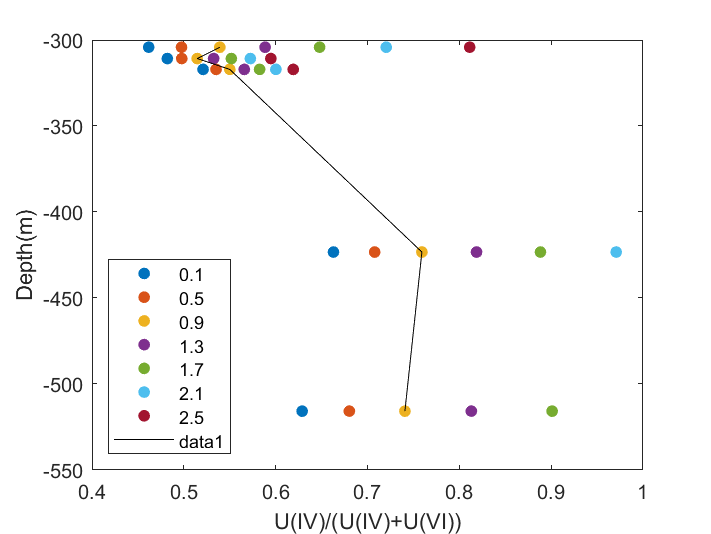

figure
plot(R, depth,".","MarkerSize",20)
xlim([0.4 1]);
legend("0.1","0.5","0.9","1.3","1.7","2.1","2.5","location","southwest");
ylabel("Depth(m)")
xlabel("U(IV)/(U(IV)+U(VI))")
hold on
plot(R(:,3),depth,"Color","k")
print(gcf,"C:\Users\19328\Desktop\Xiong-2022-U isotope\图件\UIV与UVI分离\U(IV)比值","-djpeg","-r600")
hold off

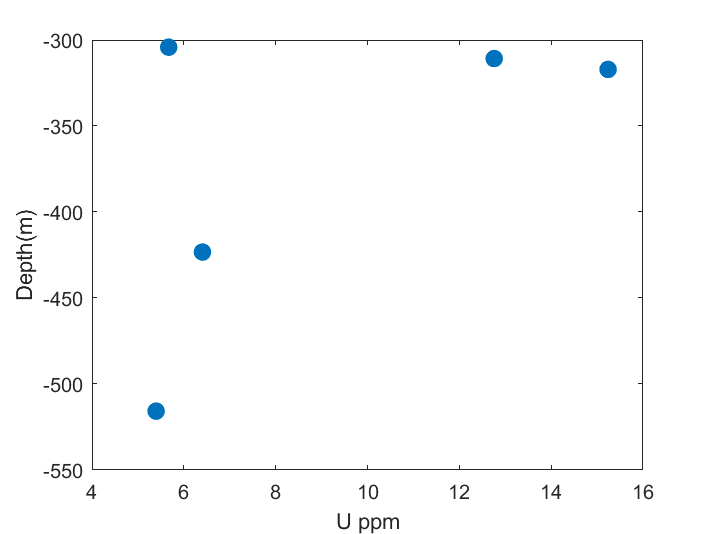


plot(Cb,depth,".","MarkerSize",30)
ylabel("Depth(m)")
xlabel("U ppm")
print(gcf,"C:\Users\19328\Desktop\Xiong-2022-U isotope\图件\UIV与UVI分离\U concentration","-djpeg","-r600")

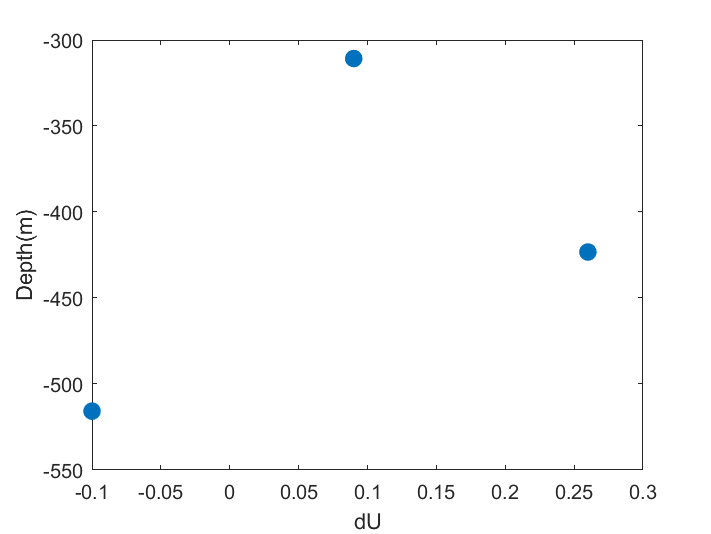


plot(dU, depth, ".","MarkerSize",30)
ylabel("Depth(m)")
xlabel("dU")
print(gcf,"C:\Users\19328\Desktop\Xiong-2022-U isotope\图件\UIV与UVI分离\U isotope","-djpeg","-r600")

% syms Cb Cvio dUb dUvi r k delta;
% eqn1 = Cb == Cb.*r + Cb.*r./k + Cvio;
% eqn2 = Cb.*dUb == Cb.*r.*(dUvi+delta) + (Cb.*r./k + Cvio).*dUvi;
% [k,delta] = sovle(eqn1,eqn2,k,delta);
